# Problem 2

Fourier Transform: transformation that changes the domain to amplitude vs. frequency from amplitude vs. time for non-periodic functions.

## Part A

Sawtooth Wave

[`x`](https://www.mathworks.com/help/signal/ref/sawtooth.html?s_tid=doc_ta#outputarg_x)` = sawtooth(`[`t`](https://www.mathworks.com/help/signal/ref/sawtooth.html?s_tid=doc_ta#inputarg_t)`)` generates a sawtooth wave with period 2*π* for the elements of the time array `t`. 

- `sawtooth` is similar to the sine function but creates a sawtooth wave with peaks of –1 and 1. 

[`Y`](https://www.mathworks.com/help/matlab/ref/fft.html#outputarg_Y)` = fft(`[`X`](https://www.mathworks.com/help/matlab/ref/fft.html#inputarg_X)`)` computes the [discrete Fourier transform](https://www.mathworks.com/help/matlab/ref/fft.html#buuutyt-6) (DFT) of `X` using a fast Fourier transform (FFT) algorithm.

- X here is our sawtooth wave that we build

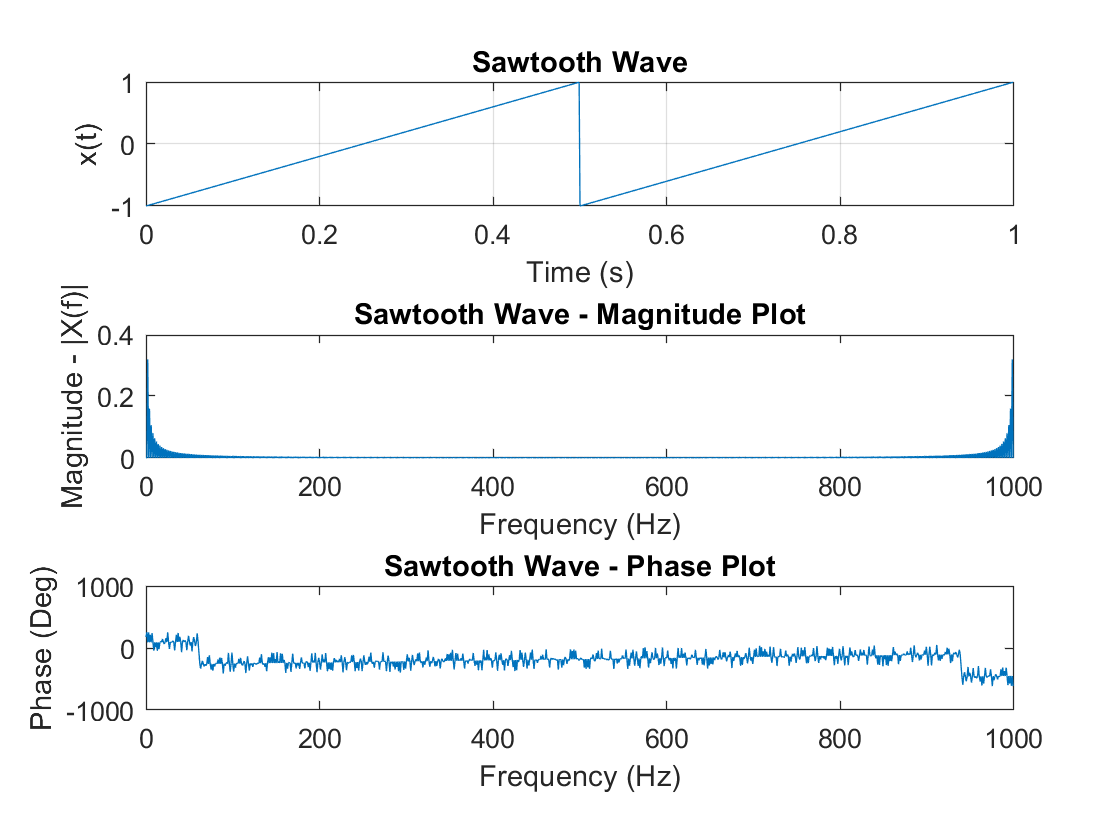


f = 1/0.5;  % Frequency 1/0.5s -- we expect a reoccurence of the wave every 0.5s
T = 1;      %Length of time of signal - 1s
Fs = 1000; %Sampling frequency -- 1 kHz standard
dt = 1/Fs; %Time steps/intervals -- increments of 0.001s
t = 0:dt:T-dt; %Time -- we subtract by dt, because we are starting at 0 instead of 1, so we're 1 index off
saw = sawtooth(2*pi*f*t); %Sawtooth wave function
figure
subplot(3,1,1)
plot(t,saw)
xlabel('Time (s)');
ylabel('x(t)');
title('Sawtooth Wave');
grid on;

% FFT Transformation
saw_fft = fft(saw);
L = length(saw_fft);
f = Fs*(0:L-1)/L;

% Magnitude
mag = abs(saw_fft/L); %Compute magnitude of FFT transformation values
subplot(3,1,2)
plot(f,mag)
xlabel('Frequency (Hz)');
ylabel('Magnitude - |X(f)|');
title('Sawtooth Wave - Magnitude Plot');

% Phase
subplot(3,1,3)
angles = angle(saw_fft); %Compute angle of FFT transformation values
phase = unwrap(angles); %Produce smoother plots w/ unwrap
phase_deg = rad2deg(phase); %Converting from rad to deg
plot(f,phase_deg);
xlabel('Frequency (Hz)');
ylabel('Phase (Deg)');
title('Sawtooth Wave - Phase Plot');

## Part B (Sawtooth Wave)

%Regenerate Sawtooth wave w/ new specified parameters
f = 1/0.5;      % Frequency - 2 Hz
T = 1;          % Length of time of signal - 1s
Fs = 1024;      % Sampling frequency
dt = 1/Fs;      % Time steps/intervals
t = 0:dt:T-dt;  % Time
N = T*Fs; % 1024 of pts.

sawb = sawtooth(2*pi*f*t); %Sawtooth wave function

% FFT Transformation
sawb_fft = fft(sawb,N);
L = length(sawb_fft);
frq = Fs*(0:L-1)/L;

% Fourier Decomposition -- Finding the frequency components that make up square wave

f1 = 1/T; %Fundamental frequency

sawb_fft_mag = abs(sawb_fft);
sawb_fft_phase = unwrap(angle(sawb_fft));


% Reconstructing square wave w/ sinusoidals
rstrb = zeros(25,N); %Storing the cosine waves -- 24 + DC components
%rstrb(1,:) = 0; %Storing DC-component in 1st row
%rstrb(2,:) = rstrb(1,:) + sawb_fft_mag(1)*cos(2*pi*f1*t_sq+sawb_fft_phase(1));
% for m = 1:round(25/2)
%     rstrb(m+1,:) = (rstrb(m-1,:) + (sawb_fft_mag(m)*cos(2*pi*m*f1*t + sawb_fft_phase(m))));
% end

Subscript indices must either be real positive integers or logicals.

figure
plot(t,sawb,t,zeros(length(t)),t,rstrb)
legend('Original Waveform','DC-component','Reconstructed Waveform')



## Part B (Square Wave)

% Generating the square wave
t_sq = linspace(0,pi,1024);
x_sq = square(t_sq);
figure
plot(t_sq,x_sq);
hold on
% Fourier Decomposition -- Finding the frequency components that make up square wave

a0 = 2* mean(x_sq); % Finding DC-component
N = length(t_sq); % # of pts.
T = 1; % 1-sec
fs = 1024; %Sampling frequency
f1 = 1/T; %Fundamental frequency

for m = 1:24
    f(m) = m*f1;
    a = (2/N)*sum(x_sq.*cos(2*pi*f(m)*t_sq)); % Cosine coefficients
    b = (2/N)*sum(x_sq.*sin(2*pi*f(m)*t_sq)); % Sine coefficients
    Z = a + b*i;
    z_mag(m) = abs(Z);
    z_phase(m) = angle(Z);
end

% Reconstructing square wave w/ sinusoidals

rstr = zeros(25,N); %Storing the cosine waves -- 24 + DC components
rstr(1,:) = a0/2; %Storingin DC-component is 1st row
rstr(2,:) = rstr(1,:) + z_mag(1)*cos(2*pi*f(1)*t_sq+z_phase(1));
for m= 2:24
   rstr(m+1,:) = rstr(m-1,:) + (z_mag(m)*cos(2*pi*f(m)*t_sq + z_phase(m)));
end
plot(t_sq,rstr)
% title('The building of a square wave: Gibbs'' effect')


# Problem 3

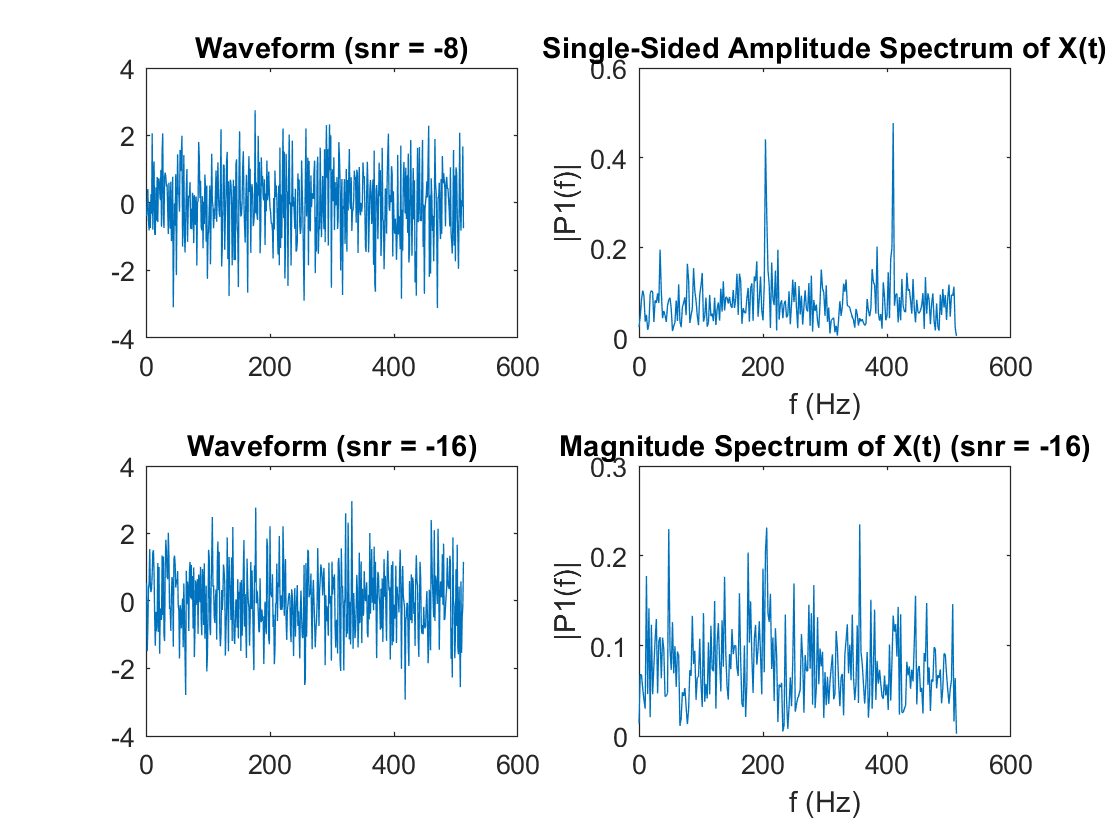

freqsin = [200, 400]; % Sine waves at 200 Hz & 400 Hz
snr_8 = -8;
snr_16 = -16;
npts = 512;

% Finiding outputs of sig_noise function
[waveform_noise8, time8, waveform8, snr8_out] = sig_noise(freqsin,snr_8, npts);
[waveform_noise16, time16, waveform16, snr16_out] = sig_noise(freqsin,snr_16, npts);

figure
subplot(2,2,1)
plot(waveform_noise8);
title('Waveform (snr = -8)')
Y8=fft(waveform_noise8);
L=length(Y8);
mag=abs(Y8/L);
P2 = mag; %Redundant magnitude spectrum
P1 = P2(1:L/2 + 1); % Splitting original spectrum in half
P1(2:end-1) = 2*P1(2:end-1); % Doubling the values in the halved spectrum to retain energy values
f = Fs*(0:(L/2))/L; % Redefining new frequency range
subplot(2,2,2)
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

subplot(2,2,3)
plot(waveform_noise16);
title('Waveform (snr = -16)')
Y16=fft(waveform_noise16);
L16=length(Y16);
mag_16=abs(Y16/L16);
P2_16 = mag_16; %Redundant magnitude spectrum
P1_16 = P2_16(1:L16/2 + 1); % Splitting original spectrum in half
P1_16(2:end-1) = 2*P1_16(2:end-1); % Doubling the values in the halved spectrum to retain energy values
f16 = Fs*(0:(L16/2))/L16; % Redefining new frequency range
subplot(2,2,4)
plot(f16,P1_16);
title('Magnitude Spectrum of X(t) (snr = -16)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

# Problem 4

## Part A

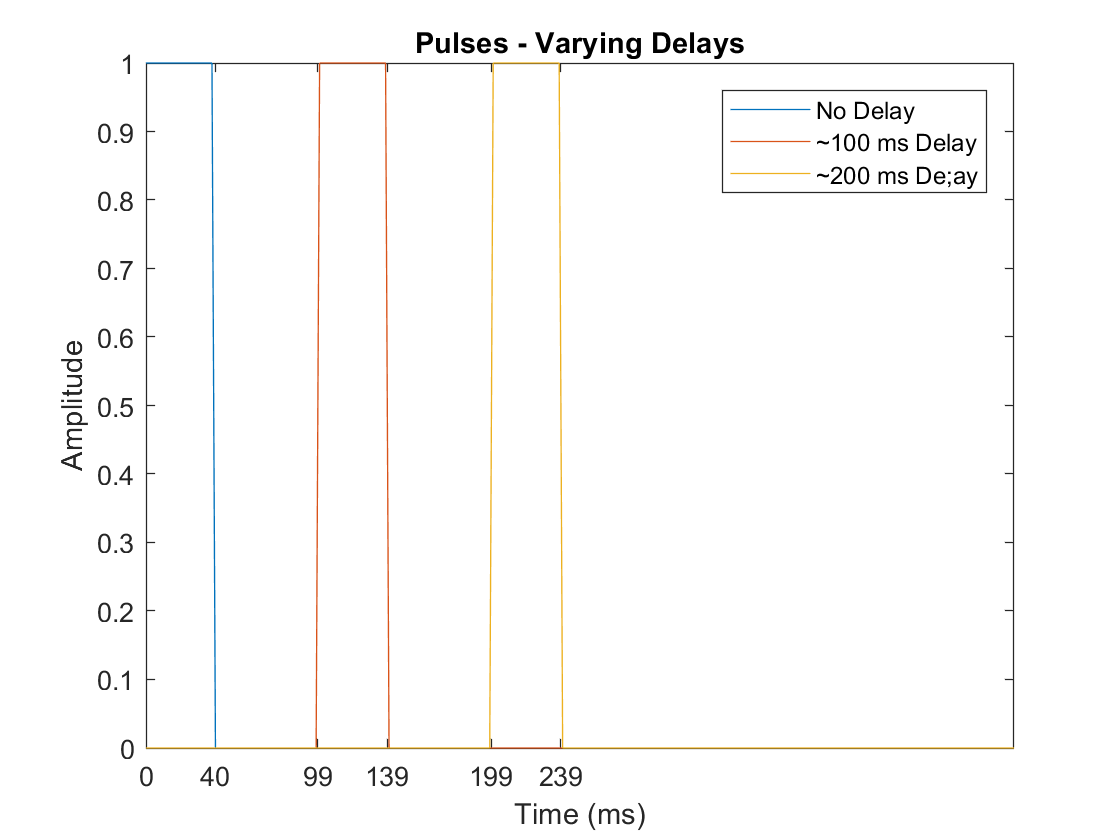

figure
t_pulse = 0:(1/500)*1000:1000 - (1/500);
plot(t_pulse,pulse1,t_pulse,pulse2,t_pulse,pulse3)
xlim([0,500]);
xticks([0 40 99 139 199 239]);
title('Pulses - Varying Delays');
xlabel('Time (ms)');
ylabel('Amplitude');
legend('No Delay','~100 ms Delay','~200 ms De;ay')

[w2,initcross2,finalcross2] = pulsewidth(pulse2,.500)

w2 = 40

initcross2 = 99

finalcross2 = 139

[w3,initcross3,finalcross3] = pulsewidth(pulse3,.500)

w3 = 40

initcross3 = 199

finalcross3 = 239

## Part B

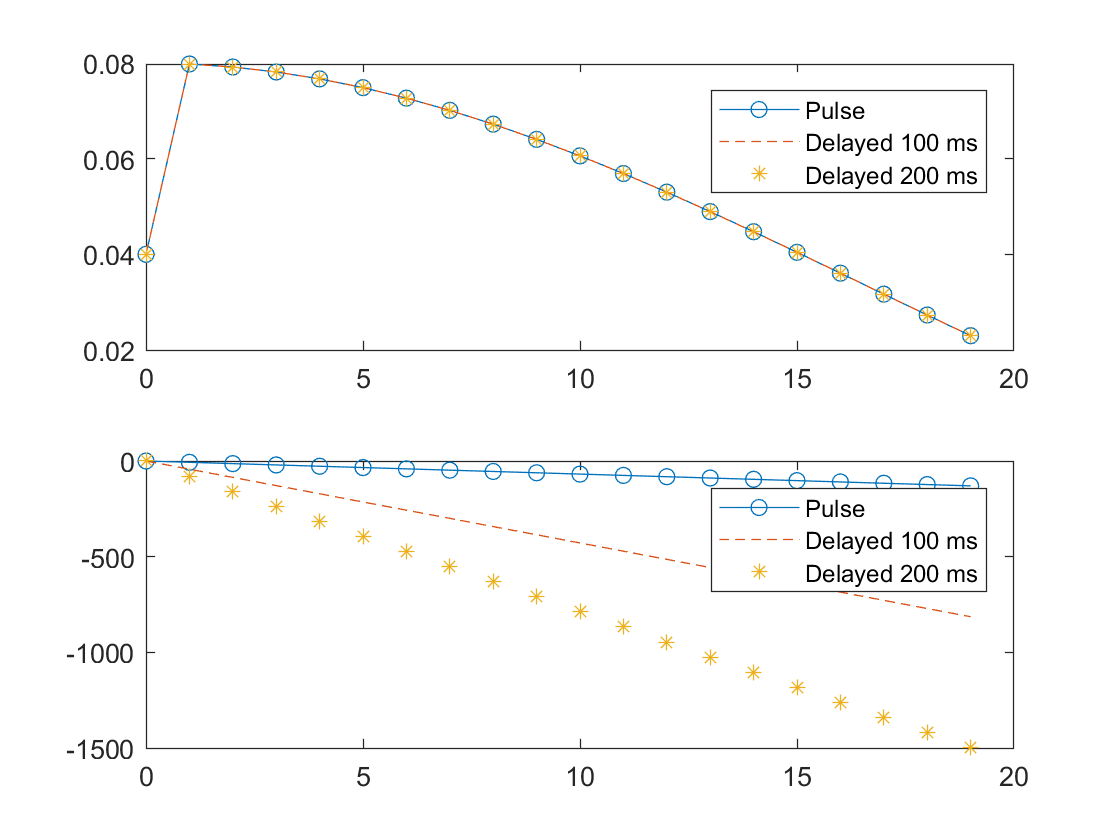

Fs = 500;
% Pulse 1 FFT
puls1_fft = fft(pulse1);
L_puls1=length(puls1_fft);
mag_puls1=abs(puls1_fft/L_puls1);
P2_puls1 = mag_puls1; %Redundant magnitude spectrum
P1_puls1 = P2_puls1(1:L_puls1/2 + 1); % Splitting original spectrum in half
P1_puls1(2:end-1) = 2*P1_puls1(2:end-1); % Doubling the values in the halved spectrum to retain energy values
f_puls1 = Fs*(0:(L_puls1/2))/L_puls1; % Redefining new frequency range
phase_puls1 = rad2deg(unwrap(angle(puls1_fft)));

% Pulse 2 FFT
puls2_fft = fft(pulse2);
L_puls2=length(puls2_fft);
mag_puls2=abs(puls2_fft/L_puls2);
P2_puls2 = mag_puls2; %Redundant magnitude spectrum
P1_puls2 = P2_puls2(1:L_puls2/2 + 1); % Splitting original spectrum in half
P1_puls2(2:end-1) = 2*P1_puls2(2:end-1); % Doubling the values in the halved spectrum to retain energy values
f_puls2 = Fs*(0:(L_puls2/2))/L_puls2; % Redefining new frequency range
phase_puls2 = rad2deg(unwrap(angle(puls2_fft)));

% Pulse 3 FFT
puls3_fft = fft(pulse3);
L_puls3=length(puls3_fft);
mag_puls3=abs(puls3_fft/L_puls3);
P2_puls3 = mag_puls3; %Redundant magnitude spectrum
P1_puls3 = P2_puls3(1:L_puls3/2 + 1); % Splitting original spectrum in half
P1_puls3(2:end-1) = 2*P1_puls3(2:end-1); % Doubling the values in the halved spectrum to retain energy values
f_puls3 = Fs*(0:(L_puls3/2))/L_puls3; % Redefining new frequency range
phase_puls3 = rad2deg(unwrap(angle(puls3_fft)));

%Superimposed Plot
subplot(2,1,1)
plot(f_puls1(1:20),P1_puls1(1:20),'o-',f_puls2(1:20),P1_puls2(1:20),'--',f_puls3(1:20),P1_puls3(1:20),'*');
title('Magnitude Spectrum');
legend('Pulse', 'Delayed 100 ms', 'Delayed 200 ms')
subplot(2,1,2)
plot(f_puls1(1:20),phase_puls1(1:20),'o-',f_puls2(1:20),phase_puls2(1:20),'--',f_puls3(1:20),phase_puls3(1:20),'*');
title('Phasee Spectrum');
legend('Pulse', 'Delayed 100 ms', 'Delayed 200 ms')

# Problem 5

## Part A

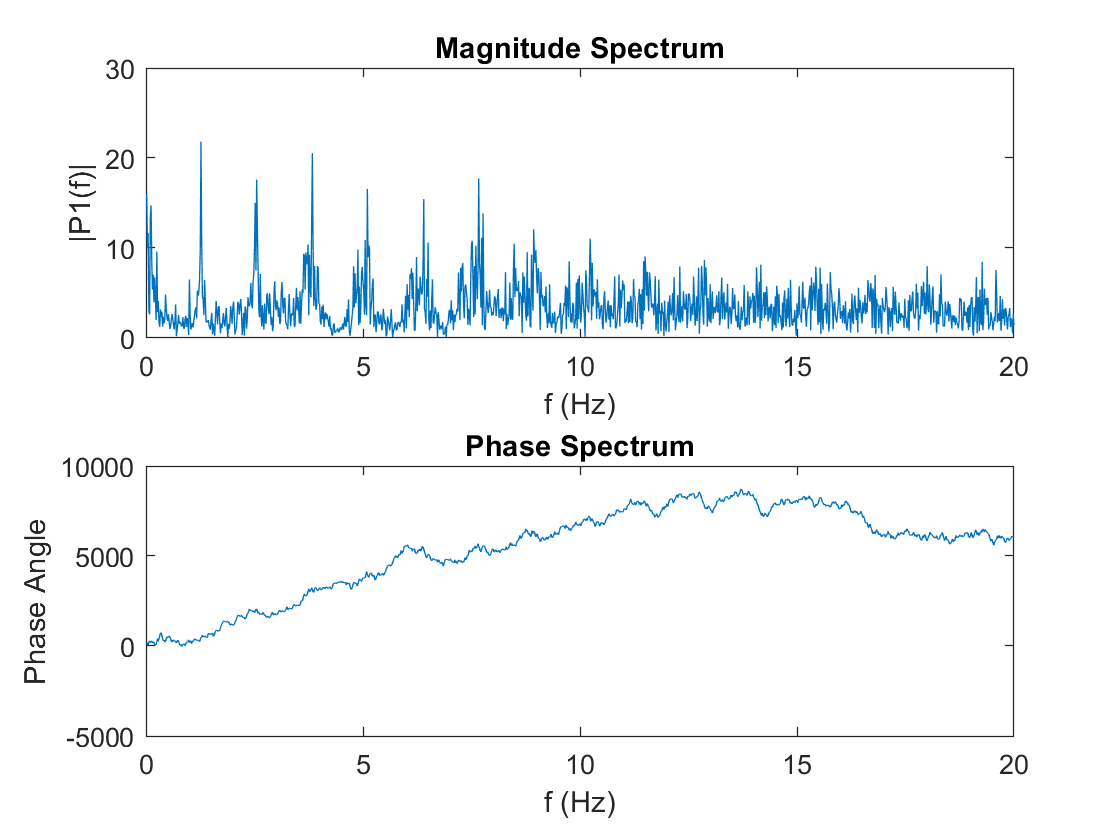

[mag_p5, freq_m5,phase_p5, freq_p5,P_sng5,P_dbl5] = fftize_np(ecg,fs_ecg);
[C,ia_p,ib_p] = intersect(freq_m5,[0 20]);
[D,ia_p,ib_p] = intersect(freq_p5,[0 20]);
figure    
    subplot(2,1,1)
    plot(freq_m5(2:1201),P_sng5(2:1201))
    title('Magnitude Spectrum')
    xlabel('f (Hz)')
    ylabel('|P1(f)|')
    
    subplot(2,1,2)
    plot(freq_p5(2:1201),phase_p5(2:1201))
    title('Phase Spectrum')
    xlabel('f (Hz)')
    ylabel('Phase Angle')

## Part B

[mag_max,i_max] = max(P_sng5(2:1201)) % Max value & index at which max value occurs

mag_max = 21.8049

i_max = 76

fmax = freq_m5(i_max)

fmax = 1.2500

hrate = 60/(1/fmax) % Heart Rate 

hrate = 75

# Problem 6

## Part A

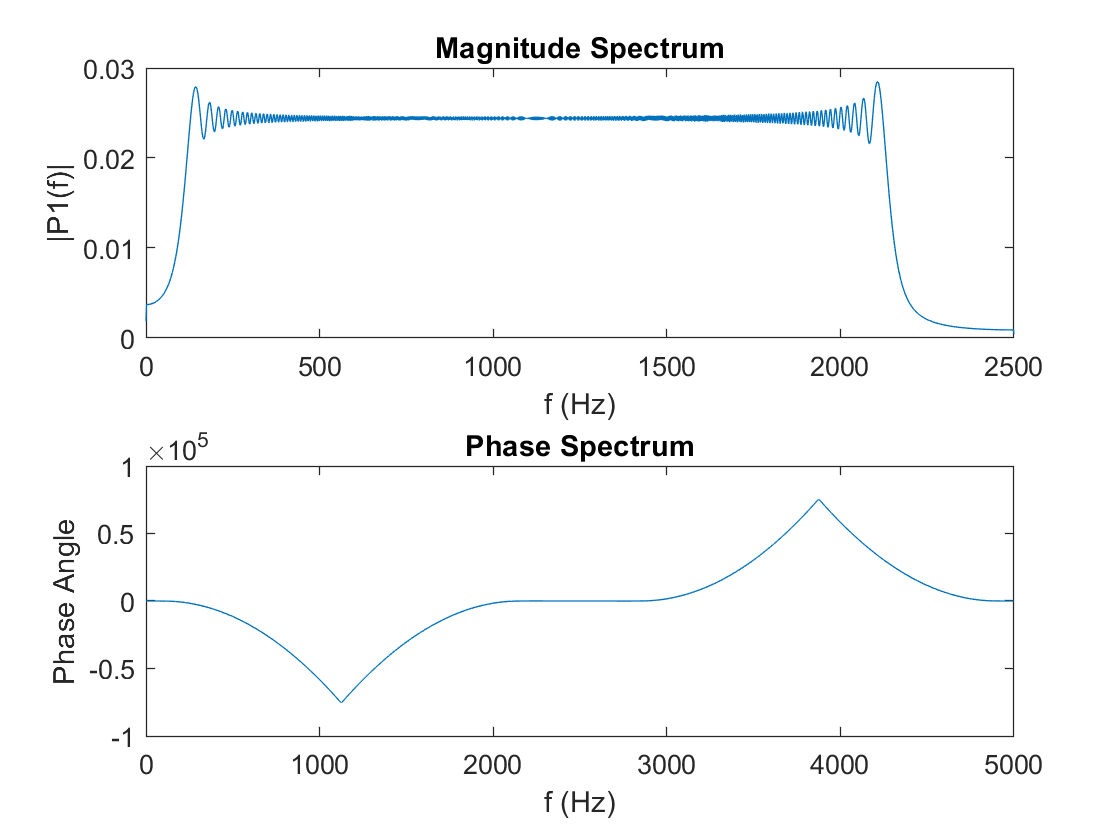

fs_chirp = 5000;
[mag_p6, freq_m6,phase_p6, freq_p6,P_sng6,P_dbl6] = fftize(chirp,fs_chirp);

## Part B

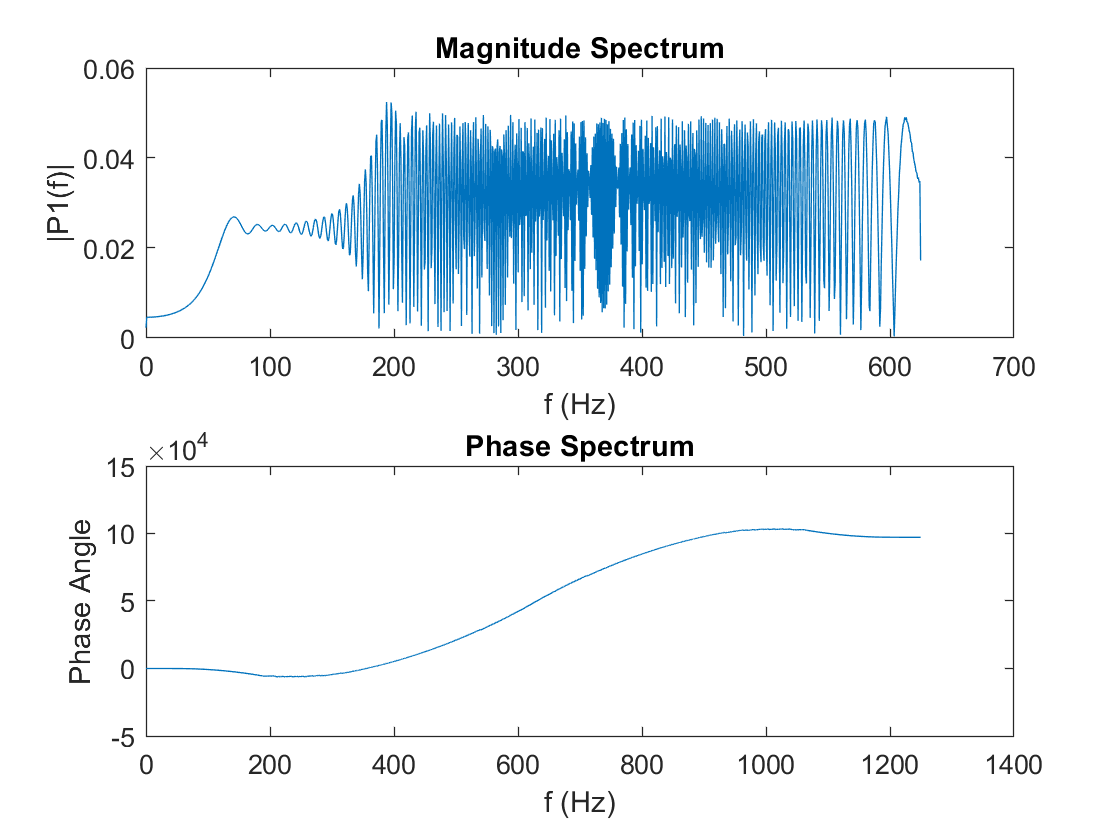

chirp_b = chirp(1:2:end); %Taking half as many observations
fs_chirp_b = fs_chirp/2;
[mag_p6b, freq_m6b,phase_p6b, freq_p6b,P_sng6b,P_dbl6b] = fftize(chirp_b,fs_chirp_b/2);

# Problem 7

## Part A

N7 = 256; %256 pt. waveform
f7 = 300; % 300Hz sine wave
snr7 = -12;
fs7 = 1000;
[waveform_noise7, time7, waveform7, snr_out7] = sig_noise(f7,snr7,N7);
[mag_p7, freq_m7,phase_p7, freq_p7,P_sng7,P_dbl7] = fftize_np(waveform_noise7,fs7);
 [r,lags] = xcorr(waveform_noise7)

r =    -3.3414    0.8148   -3.6629   -2.7201    4.1730   -7.4524    5.6023    3.2231    8.7207   -2.2567    0.5595    1.5850    8.2584   -6.0513   -2.3837   -2.1578   -7.4290   -0.4666   -9.0360    8.3703    7.0209    2.3237    3.9505   -3.0525   -8.1302    7.1388   -4.7482   -1.2499   -5.0326   -4.1457   -4.0123    6.1284    0.6872    5.6134    3.7381    1.5458    6.4271   -5.9740    3.8042   -9.4836    6.6851    5.6498    9.6498    5.2375    3.3663    5.3968   -2.5605  -11.0005   -7.2939   -4.8773


lags =   -255  -254  -253  -252  -251  -250  -249  -248  -247  -246  -245  -244  -243  -242  -241  -240  -239  -238  -237  -236  -235  -234  -233  -232  -231  -230  -229  -228  -227  -226  -225  -224  -223  -222  -221  -220  -219  -218  -217  -216  -215  -214  -213  -212  -211  -210  -209  -208  -207  -206


 r_pos = r(lags>0);
 [mag_p7b, freq_m7b,phase_p7b, freq_p7b,P_sng7b,P_dbl7b] = fftize_np(r_pos,fs7);

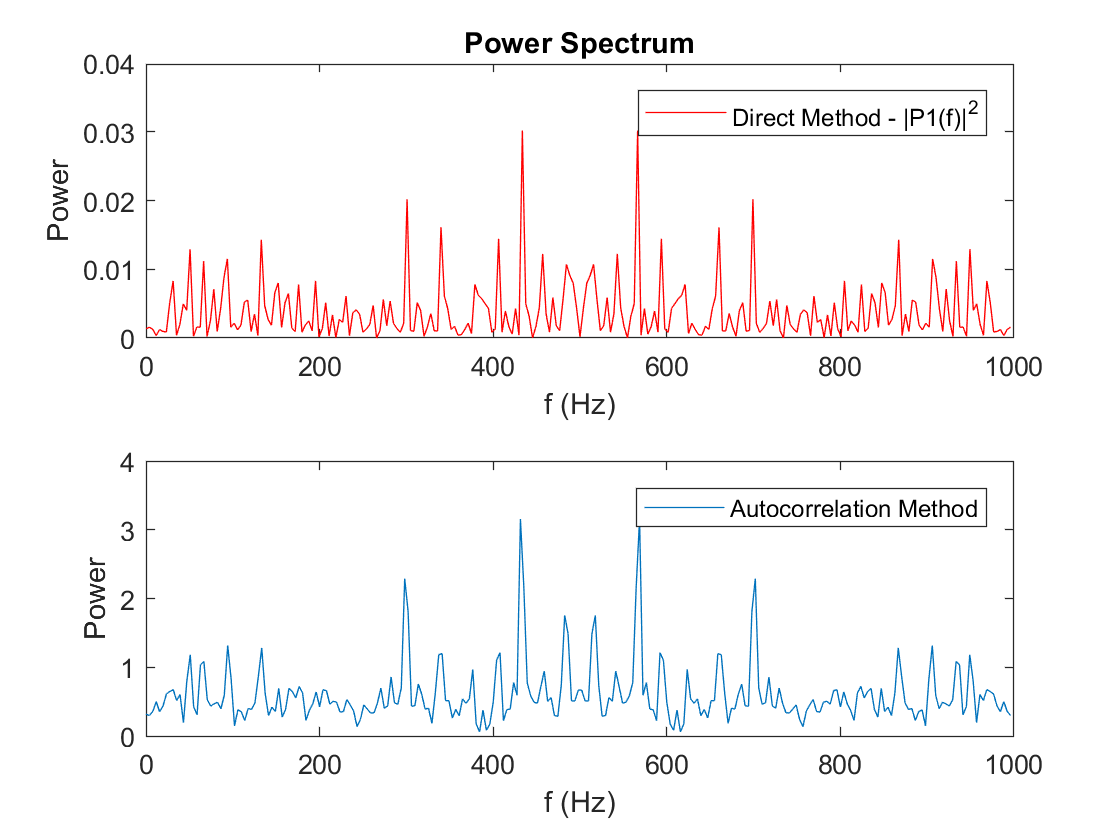


% Power Spectrum
figure
subplot(2,1,1)
 plot(freq_p7,mag_p7.^2,'r')
 title('Power Spectrum')
 legend('Direct Method - |P1(f)|^2')
 xlabel('f (Hz)')
 ylabel('Power')
 subplot(2,1,2)
 plot(freq_p7b,mag_p7b)
 xlabel('f (Hz)')
 ylabel('Power')
 legend('Autocorrelation Method')

function [waveform_noise, time, waveform, snr_out] = sig_noise(freqsin, snr, N)
% [waveform_noise, time, waveform, snr_out] = sig_noise(freqsin, snr, npts);
%   Function to generate test data Generates sinusoids in noise.

% Inputs
%    freqsin            is a vector specifing the frequency of sinusoid(s) 
%                          assuming a sample frequency of 1 KHz
%                        One sinusoid of amplitude 1 is generated for each entry
%    snr                is a vector the SNR values in db of the associated sinusoid
%                       if snr is a scalor it is used for all frequencies 
%    npts                number of points in the array
% Outputs
%    waveform_noise     is the output vector containing sinusoids and noise
%    waveform            is the output containing only sinusoids (no noise)
%    time                 is the time vector useful in ploting the waveform
%                        i.e., plot(time,waveform)
%
%
fs = 1000;       % Assume a sampling freq of 1 kHz
Ts = 1/fs;
time = (0:(N-1))*Ts;
noise = randn(1,N);      % Generate noise and calculate RMS value 
rms_noise = sqrt(mean(noise.^2));
if length(snr) < length(freqsin) && length(snr) == 1    % Check SNR vector length
    snr(2:length(freqsin)) = snr(1);    %If a scalor, use this value for all freq. 
elseif length(snr) < length(freqsin)    
    disp('Error: not enough SNR values')
    waveform_noise = rms_noise;
    return
end    
%
for i = 1:length(freqsin)
   freq_scale = freqsin(i) * 2 * pi/fs;
   x = (1:N) * freq_scale;
   snr_n = 10^(snr(i)/20);          % Convert from dB
   A = snr_n * rms_noise * 1.414;   % Determine gain for appropriate SNR
   if i == 1
     component = sin(x) * A;
      waveform = component;
         rms_sig(i) = sqrt(mean(waveform.^2));  
   else
      component = sin(x) * A;
      rms_sig(i) = sqrt(mean(component.^2));
      waveform = waveform + component;
   end
   snr_out(i) = 20 * log10(rms_sig(i)/rms_noise);  % Confirm SNR 
end
waveform_noise = waveform + noise;

end


% Plotting the magnitude and phase spectrum from the FFT
function [mag,frq_m, phase_1, frq_p,P_sng,P_dbl] = fftize(signal, Fs)
    
    fft1 = fft(signal);
    L=length(fft1);
    mag = abs(fft1/L);
    P_dbl = mag; %Redundant magnitude spectrum
    P_sng = P_dbl(1:L/2 + 1); % Splitting original spectrum in half
    P_sng(2:end-1) = 2*P_sng(2:end-1); % Doubling the values in the halved spectrum to retain energy values
    frq_m = Fs*(0:(L/2))/L; % Redefining new frequency range
    phase_1 = rad2deg(unwrap(angle(fft1)));
    frq_p = Fs*(0:(L-1))/L; % Frequency range for phase
    
    figure
    
    subplot(2,1,1)
    plot(frq_m,P_sng)
    title('Magnitude Spectrum')
    xlabel('f (Hz)')
    ylabel('|P1(f)|')
    
    subplot(2,1,2)
    plot(frq_p,phase_1)
    title('Phase Spectrum')
    xlabel('f (Hz)')
    ylabel('Phase Angle')
 
end

% Plotting the magnitude and phase spectrum from the FFT
function [mag,frq_m, phase_1, frq_p,P_sng,P_dbl] = fftize_np(signal, Fs)
    
    fft1 = fft(signal);
    L=length(fft1);
    mag = abs(fft1/L);
    P_dbl = mag; %Redundant magnitude spectrum
    P_sng = P_dbl(1:L/2 + 1); % Splitting original spectrum in half
    P_sng(2:end-1) = 2*P_sng(2:end-1); % Doubling the values in the halved spectrum to retain energy values
    frq_m = Fs*(0:(L/2))/L; % Redefining new frequency range
    phase_1 = rad2deg(unwrap(angle(fft1)));
    frq_p = Fs*(0:(L-1))/L; % Frequency range for phase 
end
